# Groceries Dataset

Clear workspace

clear all; clc; close all;

## Load data

load groceries.mat

## Find frequent articles

minSup = 0.01;
tic
[F, S, items] = findFreqItemsets(gro,minSup)

F = 1×3 struct array with fields:
    freqSets


S =   Map with properties:

        Count: 4674
      KeyType: char
    ValueType: any


items = 169×1 cell array
    {'Instant food products'}
    {'UHT-milk'             }
    {'abrasive cleaner'     }
    {'artif. sweetener'     }
    {'baby cosmetics'       }
    {'baby food'            }
    {'bags'                 }
    {'baking powder'        }
    {'bathroom cleaner'     }
    {'beef'                 }
    {'berries'              }
    {'beverages'            }
    {'bottled beer'         }
    {'bottled water'        }
    {'brandy'               }
    {'brown bread'          }
    {'butter'               }
    {'butter milk'          }
    {'cake bar'             }
    {'candles'              }
    {'candy'                }
    {'canned beer'          }
    {'canned fish'          }
    {'canned fruit'         }
    {'canned vegetables'    }
    {'cat food'             }
    {'cereals'              }
    {'chewing gum'          }
    {'chicken'              }
    {'chocolate'            }


toc

Elapsed time is 2.983148 seconds.


## Generate rules

Establisha confidence level

minConf = 0.3;
tic
rules = generateRules(F,S,minConf)

rules = 1×122 struct array with fields:
    Ante
    Conseq
    Conf
    Lift
    Sup


toc

Elapsed time is 0.229236 seconds.



fprintf('Confidence level: %.2f\n', minConf)

Confidence level: 0.30


fprintf('Rules encountered: %d\n\n', length(rules))

Rules encountered: 122



### Print rules

for i=1:length(rules)
    disp([sprintf('{%s}',items{rules(i).Ante}), ' => ', ...
          sprintf('{%s}',items{rules(i).Conseq}), ...
          sprintf('      Conf: %.2f',rules(i).Conf), ...
          sprintf('Lift: %.2f',rules(i).Lift), ...
          sprintf('Sup: %.2f',rules(i).Sup)])
end

{beef} => {root vegetables}      Conf: 0.33Lift: 3.04Sup: 0.02
{beef} => {whole milk}      Conf: 0.41Lift: 1.59Sup: 0.02
{berries} => {other vegetables}      Conf: 0.31Lift: 1.60Sup: 0.01
{berries} => {whole milk}      Conf: 0.35Lift: 1.39Sup: 0.01
{berries} => {yogurt}      Conf: 0.32Lift: 2.28Sup: 0.01
{bottled water} => {whole milk}      Conf: 0.31Lift: 1.22Sup: 0.03
{brown bread} => {whole milk}      Conf: 0.39Lift: 1.52Sup: 0.03
{butter} => {other vegetables}      Conf: 0.36Lift: 1.87Sup: 0.02
{butter} => {whole milk}      Conf: 0.50Lift: 1.95Sup: 0.03
{butter milk} => {other vegetables}      Conf: 0.37Lift: 1.92Sup: 0.01
{butter milk} => {whole milk}      Conf: 0.41Lift: 1.62Sup: 0.01
{chicken} => {other vegetables}      Conf: 0.42Lift: 2.16Sup: 0.02
{chicken} => {whole milk}      Conf: 0.41Lift: 1.60Sup: 0.02
{chocolate} => {whole milk}      Conf: 0.34Lift: 1.32Sup: 0.02
{citrus fruit} => {other vegetables}      Conf: 0.35Lift: 1.80Sup: 0.03
{citrus fruit} => {whole milk}      C

### Plot main metrics

sup  = extractfield(rules,'Sup');
conf = extractfield(rules,'Conf');
lift = extractfield(rules,'Lift');

rulestbl = struct2table(rules);

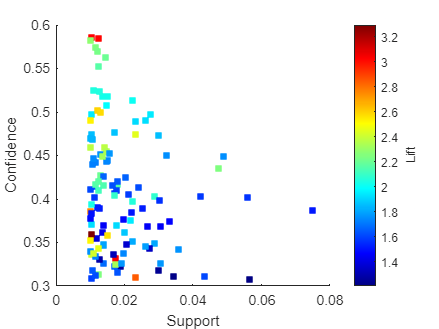

figure(1)
clf
hold on
colormap jet
scatter(sup,conf,[],lift,'s','filled')
a = colorbar;
a.Label.String = 'Lift';
xlabel('Support')
ylabel('Confidence')
hold off

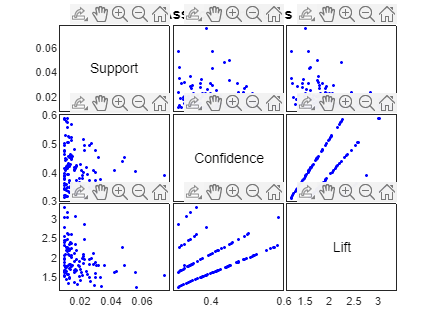

X = [sup' conf' lift'];
xnames = {'Support', 'Confidence', 'Lift'};

figure(2)
[h,ax] = gplotmatrix(X,[],[],[],[],7,[],variable=xnames);
title('Association Rules')